## **Name : ___Waris_______Damkham______**

## Student ID : ___6388014_________________________

## Section : _1_______________________________

# **Triangulation Matting Project **

Read all 4 images

A=imread('bg1.png');
B=imread('bg2.png');
C=imread('fg1.png');
D=imread('fg2.png');

Display all 4 images

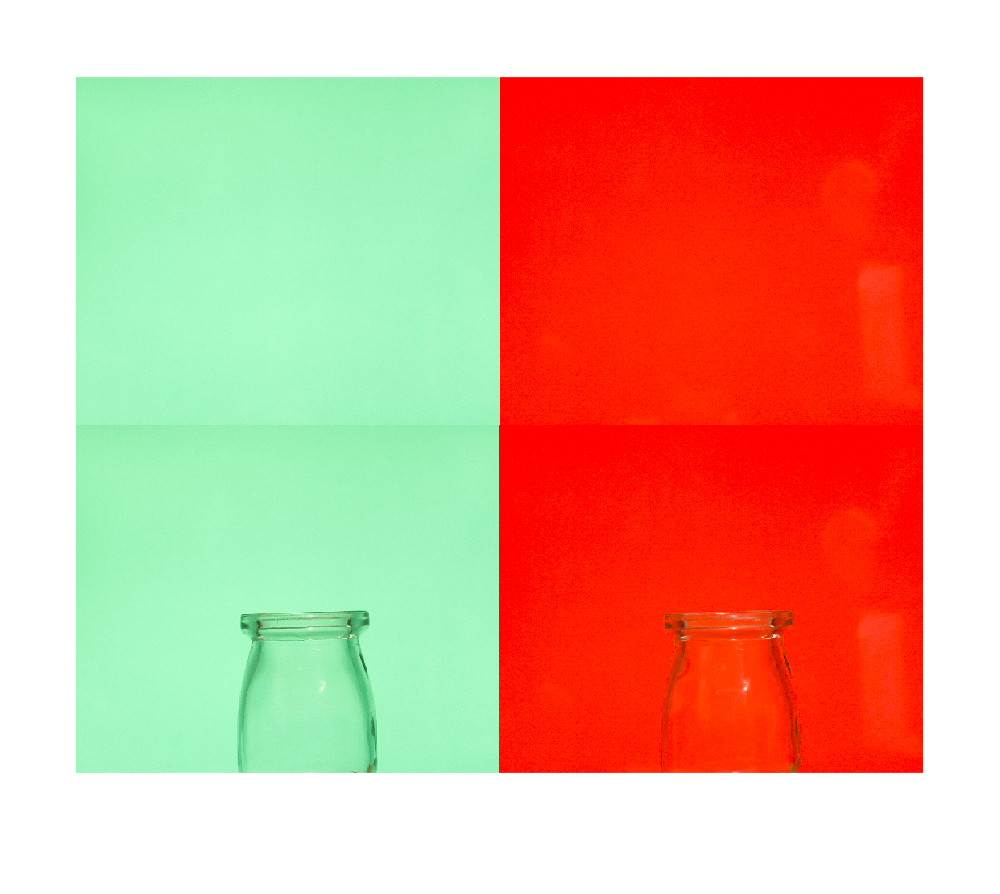

montage({A,B,C,D});

Convert to double

Cr1 = C(:,:,1); 
Cg1 = C(:,:,2); 
Cb1 = C(:,:,3); 

Cr2 = D(:,:,1); 
Cg2 = D(:,:,2); 
Cb2 = D(:,:,3);

Br1 = A(:,:,1); 
Bg1 = A(:,:,2);
Bb1 = A(:,:,3);

Br2 = B(:,:,1); 
Bg2 = B(:,:,2);
Bb2 = B(:,:,3);

Cr1 = im2double(Cr1);
Cg1 = im2double(Cg1);
Cb1 = im2double(Cb1);

Cr2 = im2double(Cr2);
Cg2 = im2double(Cg2);
Cb2 = im2double(Cb2);

Br1 = im2double(Br1); 
Bg1 = im2double(Bg1);
Bb1 = im2double(Bb1);

Br2 = im2double(Br2);
Bg2 = im2double(Bg2); 
Bb2 = im2double(Bb2); 

Compute alpha

alpha = 1 - ((((Cr1-Cr2).*(Br1-Br2)) + ((Cg1-Cg2).*(Bg1-Bg2)) + ((Cb1-Cb2).*(Bb1-Bb2)))./ ...
    (((Br1-Br2).^2) + ((Bg1-Bg2).^2) + ((Bb1-Bb2).^2)));

Compute foreground colors of object from background 1 

Fr1 = (Cr1 - (1-alpha).* Br1) ./ alpha;
Fr1(isnan(Fr1)) = 0;
Fr1 = im2gray(Fr1);

Fg1 = (Cg1 - (1-alpha).* Bg1) ./ alpha;
Fg1(isnan(Fg1)) = 0;
Fg1 = im2gray(Fg1);

Fb1 = (Cb1 - (1-alpha).* Bb1) ./ alpha;
Fb1(isnan(Fb1)) = 0;
Fb1 = im2gray(Fb1);

mat1 = (cat(3,Fr1,Fg1,Fb1));

Compute foreground colors of object from background 2

Fr2 = (Cr2 - (1-alpha).* Br2) ./ alpha;
Fr2(isnan(Fr2)) = 0;
Fr2 = im2gray(Fr2);

Fg2 = (Cg2 - (1-alpha).* Bg2) ./ alpha;
Fg2(isnan(Fg2)) = 0;
Fg2 = im2gray(Fg2);

Fb2 = (Cb2 - (1-alpha).* Bb2) ./ alpha;
Fb2(isnan(Fb2)) = 0;
Fb2 = im2gray(Fb2);

mat2 = (cat(3,Fr2,Fg2,Fb2));

Display the extracted foreground object / matte from background 1 and 2

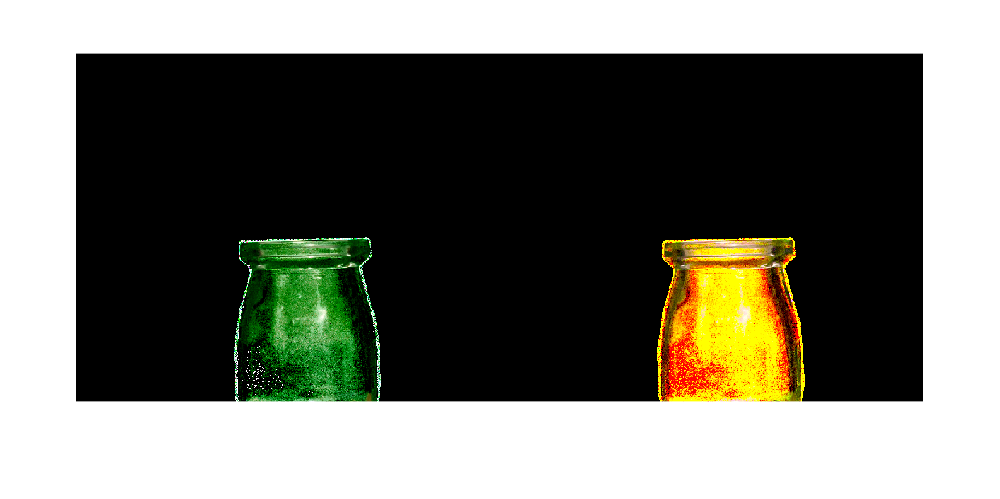

montage({mat1,mat2});

Perform the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

whitebg = (Br1.*0)+1;

white_r1 = alpha .* Fr1 + (1-alpha) .* whitebg;
white_g1 = alpha .* Fg1 + (1-alpha) .* whitebg;
white_b1 = alpha .* Fb1 + (1-alpha) .* whitebg;

white_r2 = alpha .* Fr2 + (1-alpha) .* whitebg;
white_g2 = alpha .* Fg2 + (1-alpha) .* whitebg;
white_b2 = alpha .* Fb2 + (1-alpha) .* whitebg;

comwh1 = cat(3,white_r1,white_g1,white_b1);
comwh2 = cat(3,white_r2,white_g2,white_b2);

Display the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

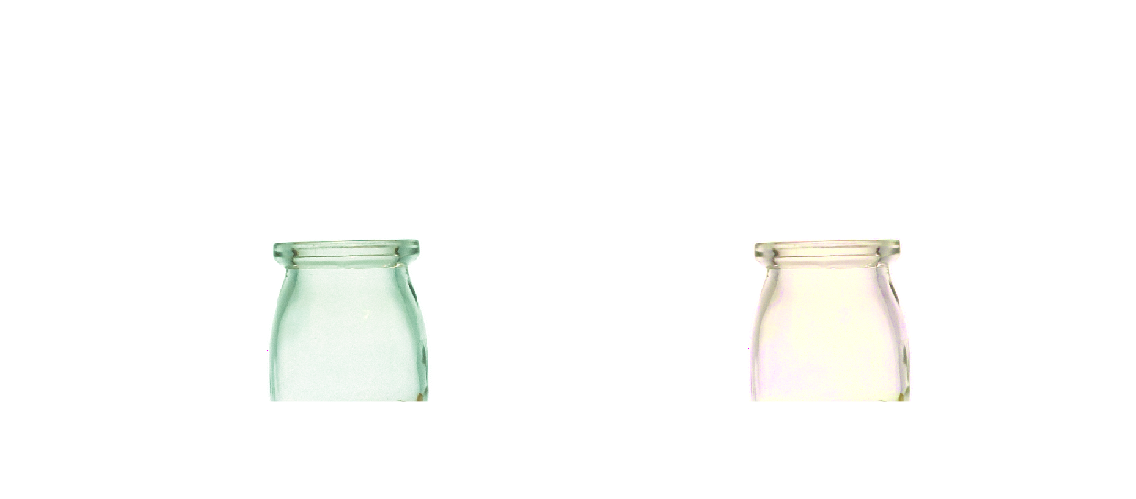

montage({comwh1,comwh2});

Read new background image to do the composition and display it.

new_bg = imread('new_bg1.png');

Perform the composition of extracted foreground object from background 1 and 2 with the new background image

newbg_r = new_bg(:,:,1);
newbg_g = new_bg(:,:,2);
newbg_b = new_bg(:,:,3);

newbg_r = im2double(newbg_r);
newbg_g = im2double(newbg_g);
newbg_b = im2double(newbg_b);

newCr1 = alpha .* Fr1 + (1-alpha) .* newbg_r;
newCg1 = alpha .* Fg1 + (1-alpha) .* newbg_g;
newCb1 = alpha .* Fb1 + (1-alpha) .* newbg_b;

newCr2 = alpha .* Fr2 + (1-alpha) .* newbg_r;
newCg2 = alpha .* Fg2 + (1-alpha) .* newbg_g;
newCb2 = alpha .* Fb2 + (1-alpha) .* newbg_b;

NewC1 = cat(3, newCr1, newCg1, newCb1);
NewC2 = cat(3, newCr2, newCg2, newCb2);

Display the composition of extracted foreground object from background 1 and 2 with the new background image

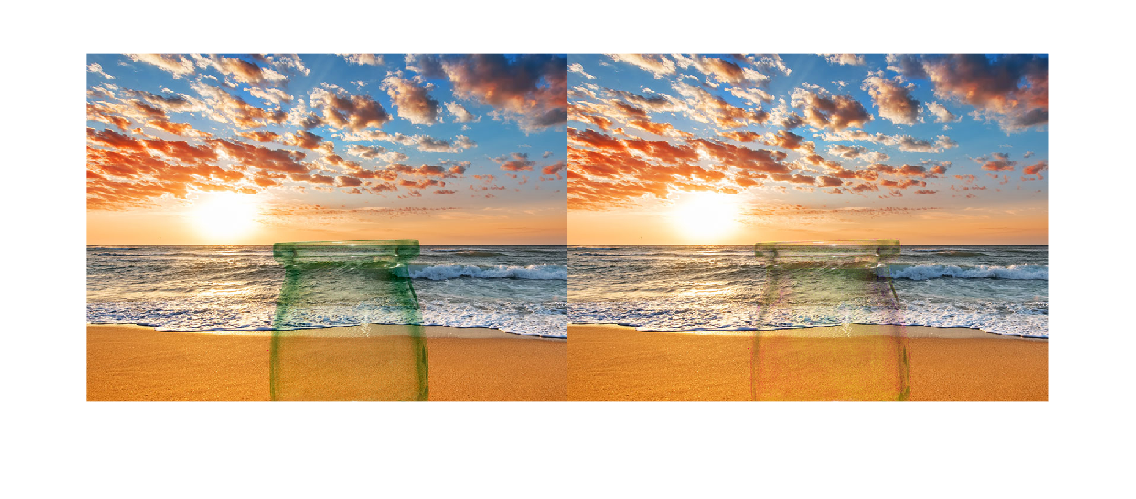

montage({NewC1,NewC2});